%%Initialise Variables for Physical Model
clear;
clc;

Kv=1880;
Motor_mass_big = 114*10^(-3);
prop_mass_big = 10*10^(-3);
Motor_mass_small = 76*10^(-3);
prop_mass_small = 6*10^(-3);
ESC_mass_same = 40*10^(-3);
m_counter= 0.45; %? not sure yet    
miu_k=0.155;
m_struct=30*10^(-3)    ; %estimate structure mass for all of it
cg_structure = 0.15; %estimate structure cg
mass_cable=0.19;
L_cable=1;
h_cable=0.33;
L_cart = 0.2104;
m_cart = 0.15;

g = 9.81;
c = 0.15;

%% Load Simulink Model
%Load PID Gains to Run Model
Kp = 333;
Ki = 95;
Kd = 55;
N = 10;
chi = 1.3325;

%Load Mission Profile for Simulink Model
%M =1 Sample Profile, M = 2 Sine Wave, M = 3 Chirp Wave, M = 4 Step Signal
M = 3;


simout = sim("Controller_Simulation.slx");
total_error = simout.Energy.Data(end) + simout.MSD.Data(end);

% --- 1. GA Hyperparameters ---
POPULATION_SIZE = 10; %Only 3 Decision Variables
GENERATIONS = 10;
MUTATION_RATE = 0.1;

GENE_BOUNDS_Kp = [100, 500]; % [Min, Max] for Kp, Ki, Kd
GENE_BOUNDS_Ki = [0,200];
GENE_BOUNDS_Kd = [0,200];
GENE_BOUNDS_chi = [1,8];

population_Kp = GENE_BOUNDS_Kp(1) + (GENE_BOUNDS_Kp(2) - GENE_BOUNDS_Kp(1)) * rand(POPULATION_SIZE, 1);
population_Ki = GENE_BOUNDS_Ki(1) + (GENE_BOUNDS_Ki(2) - GENE_BOUNDS_Ki(1)) * rand(POPULATION_SIZE, 1);
population_Kd = GENE_BOUNDS_Kd(1) + (GENE_BOUNDS_Kd(2) - GENE_BOUNDS_Kd(1)) * rand(POPULATION_SIZE, 1);
population_chi = GENE_BOUNDS_chi(1) + (GENE_BOUNDS_chi(2) - GENE_BOUNDS_chi(1)) * rand(POPULATION_SIZE, 1);
population    = cat(2,population_Kp,population_Ki,population_Kd,population_chi);


% --- 2. The Evolution Loop ---
for gen = 1:GENERATIONS
    
    % Preallocate array for errors (fitness)
    errors = zeros(POPULATION_SIZE, 1);
    
    % 1. Fitness Evaluation: Calculate error for every individual
    for i = 1:POPULATION_SIZE
        Kp =  population(i, 1);
        Ki =  population(i, 2);
        Kd =  population(i, 3);
        chi = population(i, 4);
        
        errors(i) = evaluate_pid(Kp, Ki, Kd, chi);
    end
    
    % 2. Selection: Sort the population from lowest error to highest
    [sorted_errors, sort_idx] = sort(errors);
    population = population(sort_idx, :);
    
    best_error = sorted_errors(1);
    
    % Keep the top 50% as parents (Elitism)
    num_parents = floor(POPULATION_SIZE / 2);
    parents = population(1:num_parents, :);
    
    % 3. Crossover & Mutation: Create the next generation
    next_generation = zeros(POPULATION_SIZE, 4);
    next_generation(1:num_parents, :) = parents; % Parents survive
    
    for i = (num_parents + 1):POPULATION_SIZE
        % Pick two random parents
        idx = randperm(num_parents, 2);
        parent1 = parents(idx(1), :);
        parent2 = parents(idx(2), :);
        
        % Crossover: Average the parents' genes
        child = (parent1 + parent2) / 2.0;
        
        % Mutation: Randomly tweak the child's genes
        if rand() < MUTATION_RATE
            % Add Gaussian noise to genes
            mutation_noise = 2.0 * randn(1, 4);
            child = child + mutation_noise;
            
            % Ensure PID values stay within logical bounds (no negative gains)
            child = max(child, 0); 
        end
        
        next_generation(i, :) = child;
    end
    
    % Update population
    population = next_generation;
    
    % Print progress
    if mod(gen, 10) == 0 || gen == 1
        fprintf('Generation %d | Lowest Error: %.4f\n', gen, best_error);
    end
end

Generation 1 | Lowest Error: 5897.8647
Generation 10 | Lowest Error: 5896.0683




% --- 3. Results ---
best_pid = population(1, :);
fprintf('\n--- Evolution Complete ---\n');


--- Evolution Complete ---


fprintf('Optimal Kp : %.4f\n', best_pid(1));

Optimal Kp : 332.8359


fprintf('Optimal Ki : %.4f\n', best_pid(2));

Optimal Ki : 94.9875


fprintf('Optimal Kd : %.4f\n', best_pid(3));

Optimal Kd : 55.0106


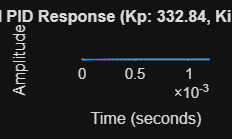

fprintf('Optimal chi : %.4f\n', best_pid(4));

% Plot the final optimal response
plot_step_response(best_pid(1), best_pid(2), best_pid(3));



% =========================================================================
% FITNESS EVALUATION FUNCTION
% =========================================================================
function total_error = evaluate_pid(Kp, Ki, Kd, chi)
    % 1. Create an input object for your specific Simulink model
    simIn = Simulink.SimulationInput('Controller_Simulation');
    
    % 2. Push the local GA variables into the simulation environment
    simIn = simIn.setVariable('Kp', Kp);
    simIn = simIn.setVariable('Ki', Ki);
    simIn = simIn.setVariable('Kd', Kd);
    simIn = simIn.setVariable('chi', chi);

    % 3. Run sine wave 
    simIn = simIn.setVariable('M',2);
    
    % 3a. Run the simulation using the input package
    simout = sim(simIn);
    
    % 3b. Extract the data and calculate the cost
    total_error_sin = (4 * simout.Energy.Data(end) / 7) + (3 * simout.MSD.Data(end) / 7);   

    % 4. Run chirp wave 
    simIn = simIn.setVariable('M',3);
    
    % 4a. Run the simulation using the input package
    simout = sim(simIn);
    
    % 4b. Extract the data and calculate the cost
    total_error_chirp = (4 * simout.Energy.Data(end) / 7) + (3 * simout.MSD.Data(end) / 7); 

    % 5. Run step wave 
    simIn = simIn.setVariable('M',4);
    
    % 3a. Run the simulation using the input package
    simout = sim(simIn);
    
    % 3b. Extract the data and calculate the cost
    total_error_step = (4 * simout.Energy.Data(end) / 7) + (3 * simout.MSD.Data(end) / 7);   


    total_error = total_error_sin + total_error_step + total_error_chirp;

    
    % Optional but recommended: Add a penalty if the simulation fails or diverges
    if simout.ErrorMessage ~= ""
        total_error = 1e6; % Massive penalty for crashing
    end
end


% =========================================================================
% HELPER FUNCTION: PLOT THE RESULT
% =========================================================================
function plot_step_response(Kp, Ki, Kd)
    s = tf('s');
    wn = 10; zeta = 0.6;
    plant = wn^2 / (s^2 + 2*zeta*wn*s + wn^2);
    
    controller = pid(Kp, Ki, Kd);
    closed_loop_sys = feedback(controller * plant, 1);
    
    figure;
    step(closed_loop_sys);
    title(sprintf('Optimized PID Response (Kp: %.2f, Ki: %.2f, Kd: %.2f)', Kp, Ki, Kd));
    grid on;
end

